sym t;
syms Theta1(t) Theta2(t) Theta3(t) Theta4(t);%make symbolic values of theta (motor angle position inputs)
Calculator=Lab2Step2();
in = [Theta1;Theta2;Theta3;Theta4];

%% calculate JW:
allTs=Calculator.joints2fk(in)

$$\left(\begin{array}{cccc} \cos\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) & 0 & -\sin\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) & 0\\ \sin\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) & 0 & \cos\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) & 0\\ 0 & -1 & 0 & \frac{48163}{500}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & \frac{13023\,\sigma_{2}}{100}\\ \sigma_{1} & \sigma_{2} & 0 & \frac{13023\,\sigma_{1}}{100}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,\Theta_{2}\left(t\right)}{180}-\frac{779938099186743}{562949953421312}\right)\\ \sigma_{2}=\cos\left(\frac{\pi \,\Theta_{2}\left(t\right)}{180}-\frac{779938099186743}{562949953421312}\right) \end{array}$$

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & 124\,\sigma_{2}\\ \sigma_{1} & \sigma_{2} & 0 & 124\,\sigma_{1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,\Theta_{3}\left(t\right)}{180}+\frac{779938099186743}{562949953421312}\right)\\ \sigma_{2}=\cos\left(\frac{\pi \,\Theta_{3}\left(t\right)}{180}+\frac{779938099186743}{562949953421312}\right) \end{array}$$

$$\left(\begin{array}{cccc} \cos\left(\frac{\pi \,\Theta_{4}\left(t\right)}{180}\right) & -\sin\left(\frac{\pi \,\Theta_{4}\left(t\right)}{180}\right) & 0 & \frac{667\,\cos\left(\frac{\pi \,\Theta_{4}\left(t\right)}{180}\right)}{5}\\ \sin\left(\frac{\pi \,\Theta_{4}\left(t\right)}{180}\right) & \cos\left(\frac{\pi \,\Theta_{4}\left(t\right)}{180}\right) & 0 & \frac{667\,\sin\left(\frac{\pi \,\Theta_{4}\left(t\right)}{180}\right)}{5}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

JW=sym('empty',[3,4]);
Ts=sym('empty',[4,4,4]);
Ts(:,:,1)=Calculator.dh2fk([0 36.076 0 0])

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & \frac{9019}{250}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} {\mathrm{empty}}_{1,1,2} & {\mathrm{empty}}_{1,2,2} & {\mathrm{empty}}_{1,3,2} & {\mathrm{empty}}_{1,4,2}\\ {\mathrm{empty}}_{2,1,2} & {\mathrm{empty}}_{2,2,2} & {\mathrm{empty}}_{2,3,2} & {\mathrm{empty}}_{2,4,2}\\ {\mathrm{empty}}_{3,1,2} & {\mathrm{empty}}_{3,2,2} & {\mathrm{empty}}_{3,3,2} & {\mathrm{empty}}_{3,4,2}\\ {\mathrm{empty}}_{4,1,2} & {\mathrm{empty}}_{4,2,2} & {\mathrm{empty}}_{4,3,2} & {\mathrm{empty}}_{4,4,2} \end{array}\right)$$

$$\left(\begin{array}{cccc} {\mathrm{empty}}_{1,1,3} & {\mathrm{empty}}_{1,2,3} & {\mathrm{empty}}_{1,3,3} & {\mathrm{empty}}_{1,4,3}\\ {\mathrm{empty}}_{2,1,3} & {\mathrm{empty}}_{2,2,3} & {\mathrm{empty}}_{2,3,3} & {\mathrm{empty}}_{2,4,3}\\ {\mathrm{empty}}_{3,1,3} & {\mathrm{empty}}_{3,2,3} & {\mathrm{empty}}_{3,3,3} & {\mathrm{empty}}_{3,4,3}\\ {\mathrm{empty}}_{4,1,3} & {\mathrm{empty}}_{4,2,3} & {\mathrm{empty}}_{4,3,3} & {\mathrm{empty}}_{4,4,3} \end{array}\right)$$

$$\left(\begin{array}{cccc} {\mathrm{empty}}_{1,1,4} & {\mathrm{empty}}_{1,2,4} & {\mathrm{empty}}_{1,3,4} & {\mathrm{empty}}_{1,4,4}\\ {\mathrm{empty}}_{2,1,4} & {\mathrm{empty}}_{2,2,4} & {\mathrm{empty}}_{2,3,4} & {\mathrm{empty}}_{2,4,4}\\ {\mathrm{empty}}_{3,1,4} & {\mathrm{empty}}_{3,2,4} & {\mathrm{empty}}_{3,3,4} & {\mathrm{empty}}_{3,4,4}\\ {\mathrm{empty}}_{4,1,4} & {\mathrm{empty}}_{4,2,4} & {\mathrm{empty}}_{4,3,4} & {\mathrm{empty}}_{4,4,4} \end{array}\right)$$

JW(:,1)=Ts(1:3,3,1)

$$JW = \left(\begin{array}{cccc} 0 & {\mathrm{empty}}_{1,2} & {\mathrm{empty}}_{1,3} & {\mathrm{empty}}_{1,4}\\ 0 & {\mathrm{empty}}_{2,2} & {\mathrm{empty}}_{2,3} & {\mathrm{empty}}_{2,4}\\ 1 & {\mathrm{empty}}_{3,2} & {\mathrm{empty}}_{3,3} & {\mathrm{empty}}_{3,4} \end{array}\right)$$

for i=1:(size(allTs,3)-1)
    Ts(:,:,i+1)=Calculator.BaseToTipT(allTs(:,:,1:i))
    JW(:,i+1)=Ts(1:3,3,i+1)
end

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & \frac{9019}{250}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) & 0 & -\sin\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) & 0\\ \sin\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) & 0 & \cos\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) & 0\\ 0 & -1 & 0 & \frac{48163}{500}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} {\mathrm{empty}}_{1,1,3} & {\mathrm{empty}}_{1,2,3} & {\mathrm{empty}}_{1,3,3} & {\mathrm{empty}}_{1,4,3}\\ {\mathrm{empty}}_{2,1,3} & {\mathrm{empty}}_{2,2,3} & {\mathrm{empty}}_{2,3,3} & {\mathrm{empty}}_{2,4,3}\\ {\mathrm{empty}}_{3,1,3} & {\mathrm{empty}}_{3,2,3} & {\mathrm{empty}}_{3,3,3} & {\mathrm{empty}}_{3,4,3}\\ {\mathrm{empty}}_{4,1,3} & {\mathrm{empty}}_{4,2,3} & {\mathrm{empty}}_{4,3,3} & {\mathrm{empty}}_{4,4,3} \end{array}\right)$$

$$\left(\begin{array}{cccc} {\mathrm{empty}}_{1,1,4} & {\mathrm{empty}}_{1,2,4} & {\mathrm{empty}}_{1,3,4} & {\mathrm{empty}}_{1,4,4}\\ {\mathrm{empty}}_{2,1,4} & {\mathrm{empty}}_{2,2,4} & {\mathrm{empty}}_{2,3,4} & {\mathrm{empty}}_{2,4,4}\\ {\mathrm{empty}}_{3,1,4} & {\mathrm{empty}}_{3,2,4} & {\mathrm{empty}}_{3,3,4} & {\mathrm{empty}}_{3,4,4}\\ {\mathrm{empty}}_{4,1,4} & {\mathrm{empty}}_{4,2,4} & {\mathrm{empty}}_{4,3,4} & {\mathrm{empty}}_{4,4,4} \end{array}\right)$$

$$JW = \left(\begin{array}{cccc} 0 & -\sin\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) & {\mathrm{empty}}_{1,3} & {\mathrm{empty}}_{1,4}\\ 0 & \cos\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) & {\mathrm{empty}}_{2,3} & {\mathrm{empty}}_{2,4}\\ 1 & 0 & {\mathrm{empty}}_{3,3} & {\mathrm{empty}}_{3,4} \end{array}\right)$$

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & \frac{9019}{250}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) & 0 & -\sin\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) & 0\\ \sin\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) & 0 & \cos\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) & 0\\ 0 & -1 & 0 & \frac{48163}{500}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{1}\,\sigma_{3} & -\sigma_{2}\,\sigma_{3} & -\sigma_{4} & \frac{13023\,\sigma_{1}\,\sigma_{3}}{100}\\ \sigma_{1}\,\sigma_{4} & -\sigma_{2}\,\sigma_{4} & \sigma_{3} & \frac{13023\,\sigma_{1}\,\sigma_{4}}{100}\\ -\sigma_{2} & -\sigma_{1} & 0 & \frac{48163}{500}-\frac{13023\,\sigma_{2}}{100}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\frac{\pi \,\Theta_{2}\left(t\right)}{180}-\frac{779938099186743}{562949953421312}\right)\\ \sigma_{2}=\sin\left(\frac{\pi \,\Theta_{2}\left(t\right)}{180}-\frac{779938099186743}{562949953421312}\right)\\ \sigma_{3}=\cos\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right)\\ \sigma_{4}=\sin\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) \end{array}$$

$$\left(\begin{array}{cccc} {\mathrm{empty}}_{1,1,4} & {\mathrm{empty}}_{1,2,4} & {\mathrm{empty}}_{1,3,4} & {\mathrm{empty}}_{1,4,4}\\ {\mathrm{empty}}_{2,1,4} & {\mathrm{empty}}_{2,2,4} & {\mathrm{empty}}_{2,3,4} & {\mathrm{empty}}_{2,4,4}\\ {\mathrm{empty}}_{3,1,4} & {\mathrm{empty}}_{3,2,4} & {\mathrm{empty}}_{3,3,4} & {\mathrm{empty}}_{3,4,4}\\ {\mathrm{empty}}_{4,1,4} & {\mathrm{empty}}_{4,2,4} & {\mathrm{empty}}_{4,3,4} & {\mathrm{empty}}_{4,4,4} \end{array}\right)$$

$$JW = \left(\begin{array}{cccc} 0 & -\sin\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) & -\sin\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) & {\mathrm{empty}}_{1,4}\\ 0 & \cos\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) & \cos\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) & {\mathrm{empty}}_{2,4}\\ 1 & 0 & 0 & {\mathrm{empty}}_{3,4} \end{array}\right)$$

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & \frac{9019}{250}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) & 0 & -\sin\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) & 0\\ \sin\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) & 0 & \cos\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) & 0\\ 0 & -1 & 0 & \frac{48163}{500}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{1}\,\sigma_{3} & -\sigma_{2}\,\sigma_{3} & -\sigma_{4} & \frac{13023\,\sigma_{1}\,\sigma_{3}}{100}\\ \sigma_{1}\,\sigma_{4} & -\sigma_{2}\,\sigma_{4} & \sigma_{3} & \frac{13023\,\sigma_{1}\,\sigma_{4}}{100}\\ -\sigma_{2} & -\sigma_{1} & 0 & \frac{48163}{500}-\frac{13023\,\sigma_{2}}{100}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\frac{\pi \,\Theta_{2}\left(t\right)}{180}-\frac{779938099186743}{562949953421312}\right)\\ \sigma_{2}=\sin\left(\frac{\pi \,\Theta_{2}\left(t\right)}{180}-\frac{779938099186743}{562949953421312}\right)\\ \sigma_{3}=\cos\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right)\\ \sigma_{4}=\sin\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) \end{array}$$

$$JW = \left(\begin{array}{cccc} 0 & -\sin\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) & -\sin\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) & -\sin\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right)\\ 0 & \cos\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) & \cos\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right) & \cos\left(\frac{\pi \,\Theta_{1}\left(t\right)}{180}\right)\\ 1 & 0 & 0 & 0 \end{array}\right)$$


%% calculate JP:
dT1dt=diff(Theta1,t);
dT2dt=diff(Theta2,t);
dT3dt=diff(Theta3,t);
dT4dt=diff(Theta4,t);

BtT=Calculator.BaseToTipT(Calculator.joints2fk(in)); %calcualted Base to Tip Transformation matrix
positionJac=jacobian(BtT(1:3,4),t);

%===========chat-gpt==========
% Extract coefficients element-wise
coefficients = cell(size(positionJac));
for i = 1:numel(positionJac)
    coefficients{i} = coeffs(positionJac(i), [dT4dt, dT3dt, dT2dt,dT1dt]); %
end
%=============================
JP=sym('empty',[3,4]);
for i=1:2
    JP(i,:)=coefficients{i};
end
JP(3,:)=[0,coefficients{3}];


%% combine JP & JW to get J
J=[JP;JW]

simplify(J)

$$ans = \begin{array}{l} \left(\begin{array}{cccc} -\frac{\pi \,\sin\left(\sigma_{1}\right)\,\sigma_{2}}{18000} & -\frac{\pi \,\cos\left(\sigma_{1}\right)\,\sigma_{3}}{18000} & -\frac{\pi \,\cos\left(\sigma_{1}\right)\,\sigma_{5}}{900} & -\frac{667\,\pi \,\cos\left(\sigma_{1}\right)\,\sin\left(\sigma_{8}\right)}{900}\\ \frac{\pi \,\cos\left(\sigma_{1}\right)\,\sigma_{2}}{18000} & -\frac{\pi \,\sin\left(\sigma_{1}\right)\,\sigma_{3}}{18000} & -\frac{\pi \,\sin\left(\sigma_{1}\right)\,\sigma_{5}}{900} & -\frac{667\,\pi \,\sin\left(\sigma_{8}\right)\,\sin\left(\sigma_{1}\right)}{900}\\ 0 & -\frac{1447\,\pi \,\cos\left(\sigma_{7}\right)}{2000}-\sigma_{4}-\sigma_{6} & -\sigma_{4}-\sigma_{6} & -\sigma_{4}\\ 0 & -\sin\left(\sigma_{1}\right) & -\sin\left(\sigma_{1}\right) & -\sin\left(\sigma_{1}\right)\\ 0 & \cos\left(\sigma_{1}\right) & \cos\left(\sigma_{1}\right) & \cos\left(\sigma_{1}\right)\\ 1 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\pi \,\Theta_{1}\left(t\right)}{180}\\ \sigma_{2}=12400\,\cos\left(\sigma_{9}\right)+13023\,\cos\left(\sigma_{7}\right)+13340\,\cos\left(\sigma_{8}\right)\\ \sigma_{3}=12400\,\sin\left(\sigma_{9}\right)+13023\,\sin\left(\sigma_{7}\right)+13340\,\sin\left(\sigma_{8}\right)\\ \sigma_{4}=\frac{667\,\pi \,\cos\left(\sigma_{8}\right)}{900}\\ \sigma_{5}=620\,\sin\left(\sigma_{9}\right)+667\,\sin\left(\sigma_{8}\right)\\ \sigma_{6}=\frac{31\,\pi \,\cos\left(\sigma_{9}\right)}{45}\\ \sigma_{7}=\frac{\pi \,\Theta_{2}\left(t\right)}{180}-\frac{779938099186743}{562949953421312}\\ \sigma_{8}=\frac{\pi \,\left(\Theta_{2}\left(t\right)+\Theta_{3}\left(t\right)+\Theta_{4}\left(t\right)\right)}{180}\\ \sigma_{9}=\frac{\pi \,\left(\Theta_{2}\left(t\right)+\Theta_{3}\left(t\right)\right)}{180} \end{array}$$

save('SymbolicJ.mat','J');

Test

calc=Lab2Step2();
m=Model(false);

180/pi

ans = 57.2958


calc.calculateJac([0,0,0,0])

ans =          0    2.2340         0         0
    4.9114         0         0         0
         0   -4.9114   -4.4925   -2.3283
         0         0         0         0
         0    1.0000    1.0000    1.0000
    1.0000         0         0         0


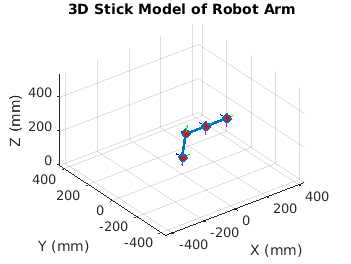

ans =     1.0000         0         0  281.3999
   -0.0000    0.0000    1.0000   -0.0000
         0   -1.0000    0.0000  224.3254
         0         0         0    1.0000


m.plot_arm([0,0,0,0])

calc.calculateJac([10,20,-30,-45])

ans =    -0.8030    4.1746    2.2483    1.8782
    4.5542    0.7361    0.3964    0.3312
         0   -4.6245   -3.4668   -1.3354
         0   -0.1736   -0.1736   -0.1736
         0    0.9848    0.9848    0.9848
    1.0000         0         0         0


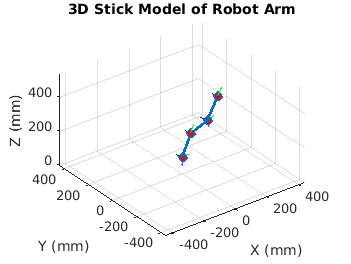

ans =     0.5649    0.8067   -0.1736  260.9368
    0.0996    0.1422    0.9848   46.0102
    0.8192   -0.5736    0.0000  339.2049
         0         0         0    1.0000


m.plot_arm([10,20,-30,-45])

calc.calculateJac([0,-10.51,-79.38,0])

ans =          0    6.7654    4.4925    2.3283
    0.0130         0         0         0
         0   -0.0130   -0.0086   -0.0045
         0         0         0         0
         0    1.0000    1.0000    1.0000
    1.0000         0         0         0


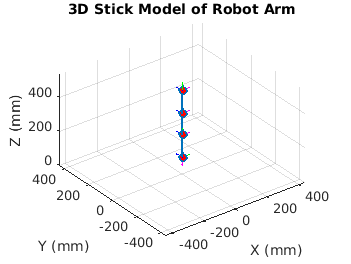

ans =     0.0019    1.0000         0    0.7434
   -0.0000    0.0000    1.0000   -0.0000
    1.0000   -0.0019    0.0000  483.9553
         0         0         0    1.0000


m.plot_arm([0,-10.51,-79.38,0])